%% resultados_MPC_figuras_memoria.m
% Comparación del controlador MPC frente a:
%   - Base turbulento
%   - IPC integral
%   - PI-IPC
%
% El MPC se evalúa mediante señales de pitch precomputadas/open-loop
% en el modelo no lineal de OpenFAST.
%
% Ventana de análisis:
%   t >= 500 s
%
% Salida:
%   Resultados/Figuras_Memoria/MPC

clear; clc; close all;

%% Rutas

rootDir = fullfile(getenv('USERPROFILE'), 'Desktop', 'TFM_OpenFast');

matlabDir = fullfile(rootDir, 'Matlab');
addpath(genpath(matlabDir));

if isempty(which('ReadFASTbinary'))

    d = dir(fullfile(rootDir, '**', 'ReadFASTbinary.m'));

    if isempty(d)
        error('No se encuentra ReadFASTbinary.m dentro de TFM_OpenFast.');
    else
        addpath(genpath(d(1).folder));
        fprintf('ReadFASTbinary añadido desde:\n%s\n', fullfile(d(1).folder, d(1).name));
    end
end

outFigDir = fullfile(rootDir, 'Resultados', 'Figuras_Memoria', 'MPC');

if ~exist(outFigDir, 'dir')
    mkdir(outFigDir);
end

%% Configuración de análisis

tTrans = 500;
tZoom  = [560 620];

mDEL   = 10;
NeqDEL = 1e6;

% Debe ser el mismo valor usado en los scripts IPC para comparar NAT
pitchRateMax_deg_s = 8;

%% Definición de casos
% IMPORTANTE:
% Revisa las carpetas de OL base y MPC. He puesto nombres probables.
% Si tu carpeta tiene otro nombre, cambia solamente el campo .dir.

casos = struct([]);

casos(1).controlador = "Base";
casos(1).tag = "Base";
casos(1).main = true;
casos(1).dir = fullfile(rootDir, 'Resultados', 'CasoB_v16_turbulento');
casos(1).priorityDirs = string(fullfile(rootDir, 'Resultados', 'CasoB_v16_turbulento'));
casos(1).searchTerms = ["CasoB", "turb"];

casos(2).controlador = "IPC integral";
casos(2).tag = "IPC_integral";
casos(2).main = true;
casos(2).dir = fullfile(rootDir, 'Resultados', 'Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento');
casos(2).priorityDirs = string(fullfile(rootDir, 'Resultados', ...
    'Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento'));
casos(2).searchTerms = ["Controlador1", "turb"];

casos(3).controlador = "PI-IPC";
casos(3).tag = "PI_IPC";
casos(3).main = true;
casos(3).dir = fullfile(rootDir, 'Resultados', 'Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento');
casos(3).priorityDirs = string(fullfile(rootDir, 'Resultados', ...
    'Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento'));
casos(3).searchTerms = ["Controlador2", "turb"];

% Caso opcional para comprobar que el modo open-loop no altera la referencia
casos(4).controlador = "OL base";
casos(4).tag = "OL_base";
casos(4).main = false;
casos(4).dir = string(fullfile(rootDir, 'Resultados', 'MPC_OL_BASE_CasoB_v16_turbulento_FIX'));
casos(4).priorityDirs = [
    string(fullfile(rootDir, 'Resultados', 'MPC_OL_BASE_CasoB_v16_turbulento_FIX'))
    string(fullfile(rootDir, 'Resultados', 'MPC_OL_BASE_CasoB_v16_turbulento'))
    string(fullfile(rootDir, 'Resultados', 'OL_BASE_CasoB_v16_turbulento'))
    string(fullfile(rootDir, 'Resultados', 'Controlador3_OL_BASE_CasoB_v16_turbulento'))
];
casos(4).searchTerms = ["OL", "BASE", "turb"];

casos(5).controlador = "MPC";
casos(5).tag = "MPC";
casos(5).main = true;
casos(5).dir = string(fullfile(rootDir, 'Resultados', 'MPC_OL_MPC_CasoB_v16_turbulento_FIX'));
casos(5).priorityDirs = [
    string(fullfile(rootDir, 'Resultados', 'MPC_OL_MPC_CasoB_v16_turbulento_FIX'))
    string(fullfile(rootDir, 'Resultados', 'MPC_OL_MPC_CasoB_v16_turbulento'))
    string(fullfile(rootDir, 'Resultados', 'OL_MPC_CasoB_v16_turbulento'))
    string(fullfile(rootDir, 'Resultados', 'Controlador3_MPC_OL_CasoB_v16_turbulento'))
    string(fullfile(rootDir, 'Resultados', 'Controlador3_MPC_CasoB_v16_turbulento'))
];
casos(5).searchTerms = ["MPC", "turb"];

%% Localizar archivos .outb

casosValidos = struct([]);
n = 0;

for i = 1:numel(casos)

    [fileOutb, found] = localizarOutb(rootDir, casos(i).priorityDirs, casos(i).searchTerms, casos(i).controlador);

    if ~found
        if casos(i).controlador == "OL base"
            warning('No se encontró OL base. Se omite este caso opcional.');
            continue;
        else
            error('No se encontró .outb para el caso obligatorio: %s', casos(i).controlador);
        end
    end

    n = n + 1;
    casosValidos(n).controlador = casos(i).controlador;
    casosValidos(n).tag = casos(i).tag;
    casosValidos(n).main = casos(i).main;
    casosValidos(n).outb = fileOutb;

    fprintf('\n%s\n%s\n', casosValidos(n).controlador, casosValidos(n).outb);
end


Base
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb

IPC integral
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb

PI-IPC
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb

OL base
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\MPC_OL_BASE_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb

MPC
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\MPC_OL_MPC_CasoB_v16_turbulento_FIX\IEA-15-240-RWT-UMaineSemi.outb



casos = casosValidos;

%% Lectura de señales

for i = 1:numel(casos)

    tmp = leerCasoOpenFAST(casos(i).outb, casos(i).controlador, tTrans);

    if i == 1
        S = repmat(tmp, numel(casos), 1);
    else
        tmp = orderfields(tmp, S(1));
        S(i) = tmp;
    end
end

Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 19:18:39 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".
Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 15-Aug-2026 at 23:02:58 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; 


%% Cálculo de métricas absolutas

tablaMPC_abs = table();

for i = 1:numel(S)

    fila = table();

    fila.Controlador = string(S(i).controlador);
    fila.Tiempo_analisis_s = max(S(i).t) - min(S(i).t);

    fila.Mean_GenPwr_MW = mean(S(i).GenPwr_MW, 'omitnan');
    fila.Std_GenPwr_MW  = std(S(i).GenPwr_MW, 'omitnan');

    fila.Mean_RotSpeed_rpm = mean(S(i).RotSpeed_rpm, 'omitnan');
    fila.Std_RotSpeed_rpm  = std(S(i).RotSpeed_rpm, 'omitnan');

    fila.Mean_BldPitch_deg = mean(S(i).BldPitchMean_deg, 'omitnan');
    fila.Std_BldPitch_deg  = std(S(i).BldPitchMean_deg, 'omitnan');

    fila.RMS_PtfmPitch_deg = rmsDemean(S(i).PtfmPitch_deg);
    fila.RMS_PtfmSurge_m   = rmsDemean(S(i).PtfmSurge_m);

    fila.DEL_RootMyb1_MNm = calcDEL(S(i).RootMyb1_MNm, mDEL, NeqDEL);
    fila.DEL_RootMyb2_MNm = calcDEL(S(i).RootMyb2_MNm, mDEL, NeqDEL);
    fila.DEL_RootMyb3_MNm = calcDEL(S(i).RootMyb3_MNm, mDEL, NeqDEL);

    fila.DEL_RootMyb_mean_MNm = mean([ ...
        fila.DEL_RootMyb1_MNm, ...
        fila.DEL_RootMyb2_MNm, ...
        fila.DEL_RootMyb3_MNm], 'omitnan');

    fila.RMS_Mtilt_MNm = rmsDemean(S(i).Mtilt_MNm);
    fila.RMS_Myaw_MNm  = rmsDemean(S(i).Myaw_MNm);

    fila.RMS_IPC_pitch_deg = calcRMS_IPC(S(i).BldPitch_deg);
    fila.Max_IPC_pitch_deg = calcMax_IPC(S(i).BldPitch_deg);

    fila.NAT_pitch_total_pct = calcNAT(S(i).BldPitch_deg, S(i).t, pitchRateMax_deg_s);
    fila.NAT_IPC_pitch_pct   = calcNAT(calcPitchIPC(S(i).BldPitch_deg), S(i).t, pitchRateMax_deg_s);

    tablaMPC_abs = [tablaMPC_abs; fila];
end

disp("=== TABLA ABSOLUTA MPC ===");

=== TABLA ABSOLUTA MPC ===


disp(tablaMPC_abs);

     Controlador      Tiempo_analisis_s    Mean_GenPwr_MW    Std_GenPwr_MW    Mean_RotSpeed_rpm    Std_RotSpeed_rpm    Mean_BldPitch_deg    Std_BldPitch_deg    RMS_PtfmPitch_deg    RMS_PtfmSurge_m    DEL_RootMyb1_MNm    DEL_RootMyb2_MNm    DEL_RootMyb3_MNm    DEL_RootMyb_mean_MNm    RMS_Mtilt_MNm    RMS_Myaw_MNm    RMS_IPC_pitch_deg    Max_IPC_pitch_deg    NAT_pitch_total_pct    NAT_IPC_pitch_pct
    ______________    _________________    ______________    _____________    _________________    ________________    _________________    <


%% Variación porcentual respecto al caso base original

varsPct = [
    "Mean_GenPwr_MW"
    "Std_GenPwr_MW"
    "Mean_RotSpeed_rpm"
    "Std_RotSpeed_rpm"
    "Mean_BldPitch_deg"
    "Std_BldPitch_deg"
    "RMS_PtfmPitch_deg"
    "RMS_PtfmSurge_m"
    "DEL_RootMyb_mean_MNm"
    "RMS_Mtilt_MNm"
    "RMS_Myaw_MNm"
    "RMS_IPC_pitch_deg"
    "Max_IPC_pitch_deg"
    "NAT_pitch_total_pct"
    "NAT_IPC_pitch_pct"
];

idxBase = tablaMPC_abs.Controlador == "Base";

if ~any(idxBase)
    error('No se encontró la fila Base.');
end

baseRow = tablaMPC_abs(idxBase,:);

tablaMPC_pct = table();

for r = 1:height(tablaMPC_abs)

    fila = table();
    fila.Controlador = tablaMPC_abs.Controlador(r);

    for v = 1:numel(varsPct)

        varName = varsPct(v);

        xCtrl = tablaMPC_abs.(varName)(r);
        xBase = baseRow.(varName)(1);

        if abs(xBase) < 1e-12
            pct = NaN;
        else
            pct = 100 * (xCtrl - xBase) / xBase;
        end

        fila.(varName + "_pct") = pct;
    end

    tablaMPC_pct = [tablaMPC_pct; fila];
end

disp("=== VARIACIÓN PORCENTUAL RESPECTO AL BASE ===");

=== VARIACIÓN PORCENTUAL RESPECTO AL BASE ===


disp(tablaMPC_pct);

     Controlador      Mean_GenPwr_MW_pct    Std_GenPwr_MW_pct    Mean_RotSpeed_rpm_pct    Std_RotSpeed_rpm_pct    Mean_BldPitch_deg_pct    Std_BldPitch_deg_pct    RMS_PtfmPitch_deg_pct    RMS_PtfmSurge_m_pct    DEL_RootMyb_mean_MNm_pct    RMS_Mtilt_MNm_pct    RMS_Myaw_MNm_pct    RMS_IPC_pitch_deg_pct    Max_IPC_pitch_deg_pct    NAT_pitch_total_pct_pct    NAT_IPC_pitch_pct_pct
    ______________    __________________    _________________    _____________________    ____________________    _____________________    ____________________    _____________________    _________________


%% Tabla compacta para memoria

controllersMain = ["Base", "IPC integral", "PI-IPC", "MPC"];
controllersMain = controllersMain(ismember(controllersMain, tablaMPC_abs.Controlador));

tablaMPC_memoria = table();

for i = 1:numel(controllersMain)

    c = controllersMain(i);

    idx = tablaMPC_abs.Controlador == c;
    idxPct = tablaMPC_pct.Controlador == c;

    fila = table();

    fila.Controlador = c;
    fila.DEL_RootMyb_MNm = tablaMPC_abs.DEL_RootMyb_mean_MNm(idx);
    fila.Delta_DEL_pct = tablaMPC_pct.DEL_RootMyb_mean_MNm_pct(idxPct);
    fila.RMS_IPC_deg = tablaMPC_abs.RMS_IPC_pitch_deg(idx);
    fila.Max_IPC_deg = tablaMPC_abs.Max_IPC_pitch_deg(idx);
    fila.NAT_IPC_pct = tablaMPC_abs.NAT_IPC_pitch_pct(idx);
    fila.RMS_Mtilt_MNm = tablaMPC_abs.RMS_Mtilt_MNm(idx);
    fila.RMS_Myaw_MNm = tablaMPC_abs.RMS_Myaw_MNm(idx);
    fila.Std_GenPwr_MW = tablaMPC_abs.Std_GenPwr_MW(idx);
    fila.RMS_PtfmPitch_deg = tablaMPC_abs.RMS_PtfmPitch_deg(idx);
    fila.RMS_PtfmSurge_m = tablaMPC_abs.RMS_PtfmSurge_m(idx);

    tablaMPC_memoria = [tablaMPC_memoria; fila];
end

disp("=== TABLA COMPACTA PARA MEMORIA ===");

=== TABLA COMPACTA PARA MEMORIA ===


disp(tablaMPC_memoria);

     Controlador      DEL_RootMyb_MNm    Delta_DEL_pct    RMS_IPC_deg    Max_IPC_deg    NAT_IPC_pct    RMS_Mtilt_MNm    RMS_Myaw_MNm    Std_GenPwr_MW    RMS_PtfmPitch_deg    RMS_PtfmSurge_m
    ______________    _______________    _____________    ___________    ___________    ___________    _____________    ____________    _____________    _________________    _______________

    "Base"                18.133                  0        8.172e-16     1.7764e-15     2.3143e-13        5.9413           5.6948          0.76509            0.67608             2.0222     
    "IPC integral"        17.121            -5.5838    

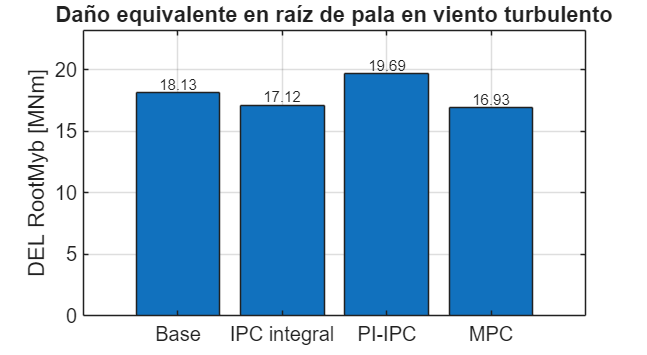


%% Guardar tablas

fileExcel = fullfile(outFigDir, 'tablas_MPC.xlsx');

writetable(tablaMPC_abs, fileExcel, 'Sheet', 'Valores_absolutos');
writetable(tablaMPC_pct, fileExcel, 'Sheet', 'Variacion_pct_base');
writetable(tablaMPC_memoria, fileExcel, 'Sheet', 'Tabla_memoria');

save(fullfile(outFigDir, 'tablas_MPC.mat'), 'tablaMPC_abs', 'tablaMPC_pct', 'tablaMPC_memoria', 'S');

%% Ajustes gráficos

set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);
set(groot, 'defaultLegendFontSize', 10);

%% ============================================================
% FIGURA 1: DEL comparativo en turbulento
% ============================================================

fig = figure('Color','w','Position',[100 100 950 520]);

Y = getMetricByController(tablaMPC_abs, controllersMain, "DEL_RootMyb_mean_MNm");

cats = categorical(controllersMain);
cats = reordercats(cats, controllersMain);

b = bar(cats, Y);
grid on; box on;
ylabel('DEL RootMyb [MNm]');
title('Daño equivalente en raíz de pala en viento turbulento');

addBarLabelsSingle(b, Y, 2);
ylim([0, max(Y)*1.18]);

guardarFigura(fig, outFigDir, 'mpc_DEL_comparativa_turbulento');

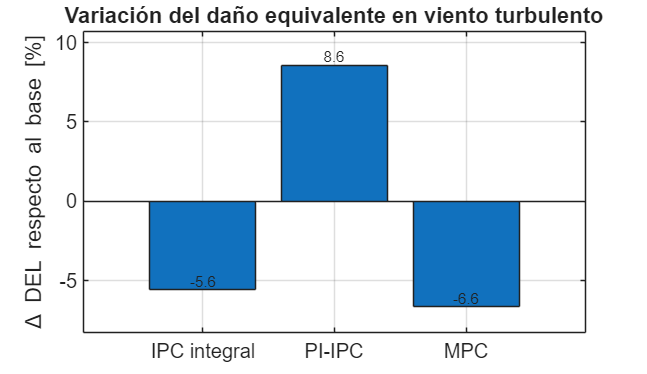


%% ============================================================
% FIGURA 2: variación porcentual de DEL
% ============================================================

controllersNoBase = controllersMain(controllersMain ~= "Base");

fig = figure('Color','w','Position',[100 100 900 520]);

Y = getMetricByController(tablaMPC_pct, controllersNoBase, "DEL_RootMyb_mean_MNm_pct");

cats = categorical(controllersNoBase);
cats = reordercats(cats, controllersNoBase);

b = bar(cats, Y);
grid on; box on;
yline(0, '--');
ylabel('\Delta DEL respecto al base [%]');
title('Variación del daño equivalente en viento turbulento');

addBarLabelsSingle(b, Y, 1);

ylimManual = [min([Y;0])*1.25, max([Y;0])*1.25 + eps];
ylim(ylimManual);

guardarFigura(fig, outFigDir, 'mpc_DEL_variacion_pct_turbulento');

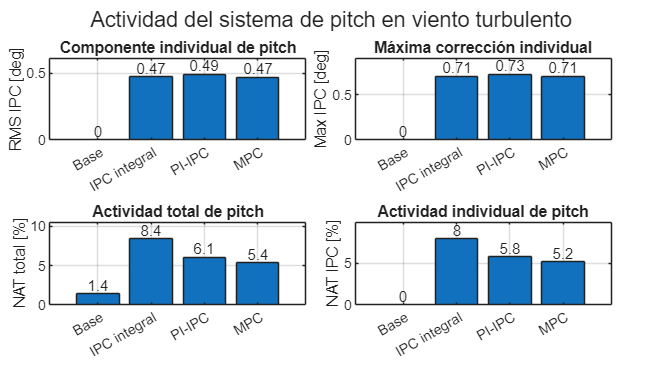


%% ============================================================
% FIGURA 3: actividad de pitch
% ============================================================

fig = figure('Color','w','Position',[100 100 1150 650]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

cats = categorical(controllersMain);
cats = reordercats(cats, controllersMain);

% RMS IPC
nexttile;
Y = getMetricByController(tablaMPC_abs, controllersMain, "RMS_IPC_pitch_deg");
b = bar(cats, Y);
grid on; box on;
ylabel('RMS IPC [deg]');
title('Componente individual de pitch');
addBarLabelsSingle(b, Y, 2);
ylim([0, max(Y)*1.25 + eps]);

% Max IPC
nexttile;
Y = getMetricByController(tablaMPC_abs, controllersMain, "Max_IPC_pitch_deg");
b = bar(cats, Y);
grid on; box on;
ylabel('Max IPC [deg]');
title('Máxima corrección individual');
addBarLabelsSingle(b, Y, 2);
ylim([0, max(Y)*1.25 + eps]);

% NAT total
nexttile;
Y = getMetricByController(tablaMPC_abs, controllersMain, "NAT_pitch_total_pct");
b = bar(cats, Y);
grid on; box on;
ylabel('NAT total [%]');
title('Actividad total de pitch');
addBarLabelsSingle(b, Y, 1);
ylim([0, max(Y)*1.25 + eps]);

% NAT IPC
nexttile;
Y = getMetricByController(tablaMPC_abs, controllersMain, "NAT_IPC_pitch_pct");
b = bar(cats, Y);
grid on; box on;
ylabel('NAT IPC [%]');
title('Actividad individual de pitch');
addBarLabelsSingle(b, Y, 1);
ylim([0, max(Y)*1.25 + eps]);

title(tl, 'Actividad del sistema de pitch en viento turbulento');

guardarFigura(fig, outFigDir, 'mpc_actividad_pitch_turbulento');

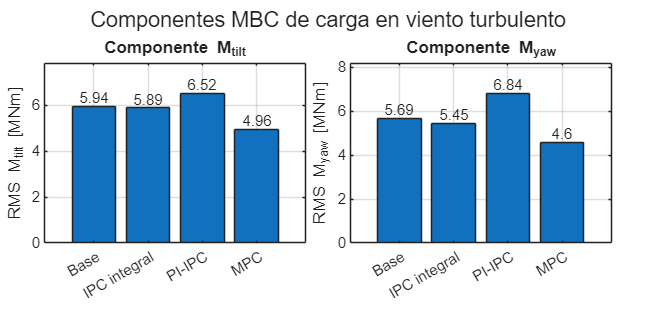


%% ============================================================
% FIGURA 4: componentes MBC RMS
% ============================================================

fig = figure('Color','w','Position',[100 100 1050 500]);
tl = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

nexttile;
Y = getMetricByController(tablaMPC_abs, controllersMain, "RMS_Mtilt_MNm");
b = bar(cats, Y);
grid on; box on;
ylabel('RMS M_{tilt} [MNm]');
title('Componente M_{tilt}');
addBarLabelsSingle(b, Y, 2);
ylim([0, max(Y)*1.2]);

nexttile;
Y = getMetricByController(tablaMPC_abs, controllersMain, "RMS_Myaw_MNm");
b = bar(cats, Y);
grid on; box on;
ylabel('RMS M_{yaw} [MNm]');
title('Componente M_{yaw}');
addBarLabelsSingle(b, Y, 2);
ylim([0, max(Y)*1.2]);

title(tl, 'Componentes MBC de carga en viento turbulento');

guardarFigura(fig, outFigDir, 'mpc_mbc_barras_turbulento');

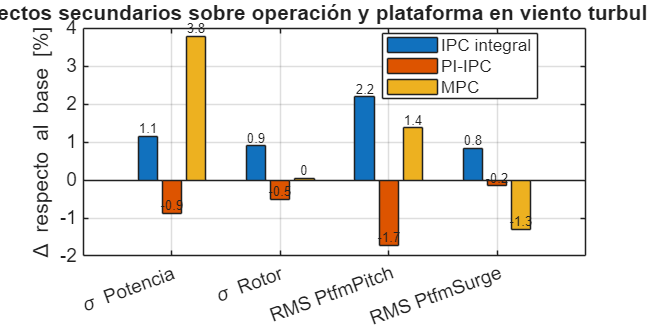


%% ============================================================
% FIGURA 5: efectos sobre operación y plataforma
% ============================================================

metricsSec = [
    "Std_GenPwr_MW_pct"
    "Std_RotSpeed_rpm_pct"
    "RMS_PtfmPitch_deg_pct"
    "RMS_PtfmSurge_m_pct"
];

namesSec = categorical({ ...
    '\sigma Potencia', ...
    '\sigma Rotor', ...
    'RMS PtfmPitch', ...
    'RMS PtfmSurge'});

namesSec = reordercats(namesSec, { ...
    '\sigma Potencia', ...
    '\sigma Rotor', ...
    'RMS PtfmPitch', ...
    'RMS PtfmSurge'});

fig = figure('Color','w','Position',[100 100 1100 560]);

Y = zeros(numel(metricsSec), numel(controllersNoBase));

for c = 1:numel(controllersNoBase)
    for m = 1:numel(metricsSec)
        Y(m,c) = getMetricByController(tablaMPC_pct, controllersNoBase(c), metricsSec(m));
    end
end

b = bar(namesSec, Y, 'grouped');
grid on; box on;
yline(0, '--');
ylabel('\Delta respecto al base [%]');
legend(controllersNoBase, 'Location','best');
title('Efectos secundarios sobre operación y plataforma en viento turbulento');
xtickangle(20);

addBarLabelsGrouped(b, Y, 1);

guardarFigura(fig, outFigDir, 'mpc_operacion_plataforma_pct_turbulento');

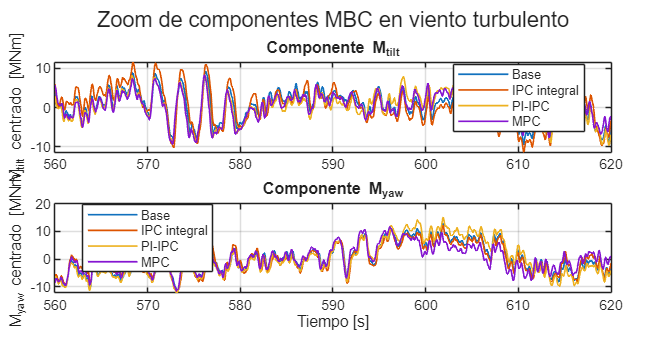


%% ============================================================
% FIGURA 6: zoom componentes MBC
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

nexttile;
hold on;

for c = 1:numel(controllersMain)

    Sc = getStructCase(S, controllersMain(c));
    idx = Sc.t >= tZoom(1) & Sc.t <= tZoom(2);

    plot(Sc.t(idx), demeanSignal(Sc.Mtilt_MNm(idx)), 'LineWidth', 1.0);
end

grid on; box on;
ylabel('M_{tilt} centrado [MNm]');
title('Componente M_{tilt}');
legend(controllersMain, 'Location','best');
xlim(tZoom);

nexttile;
hold on;

for c = 1:numel(controllersMain)

    Sc = getStructCase(S, controllersMain(c));
    idx = Sc.t >= tZoom(1) & Sc.t <= tZoom(2);

    plot(Sc.t(idx), demeanSignal(Sc.Myaw_MNm(idx)), 'LineWidth', 1.0);
end

grid on; box on;
ylabel('M_{yaw} centrado [MNm]');
xlabel('Tiempo [s]');
title('Componente M_{yaw}');
legend(controllersMain, 'Location','best');
xlim(tZoom);

title(tl, 'Zoom de componentes MBC en viento turbulento');

guardarFigura(fig, outFigDir, 'mpc_zoom_mbc_turbulento');

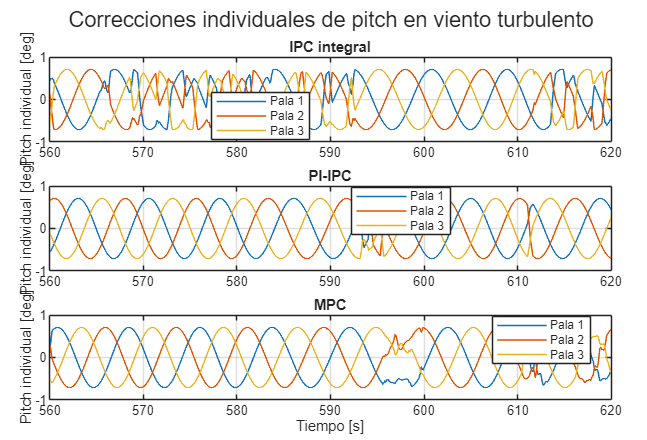


%% ============================================================
% FIGURA 7: pitch individual comparativo
% ============================================================

controllersPitch = controllersMain(controllersMain ~= "Base");

fig = figure('Color','w','Position',[100 100 1250 850]);
tl = tiledlayout(numel(controllersPitch),1,'TileSpacing','compact','Padding','compact');

for c = 1:numel(controllersPitch)

    Sc = getStructCase(S, controllersPitch(c));

    idx = Sc.t >= tZoom(1) & Sc.t <= tZoom(2);
    betaIPC = calcPitchIPC(Sc.BldPitch_deg);

    nexttile;
    plot(Sc.t(idx), betaIPC(idx,1), 'LineWidth', 0.9); hold on;
    plot(Sc.t(idx), betaIPC(idx,2), 'LineWidth', 0.9);
    plot(Sc.t(idx), betaIPC(idx,3), 'LineWidth', 0.9);

    grid on; box on;
    ylabel('Pitch individual [deg]');
    title(controllersPitch(c));
    xlim(tZoom);
    ylim([-1 1]);
    legend('Pala 1','Pala 2','Pala 3','Location','best');
end

xlabel('Tiempo [s]');
title(tl, 'Correcciones individuales de pitch en viento turbulento');

guardarFigura(fig, outFigDir, 'mpc_pitch_individual_comparativo');

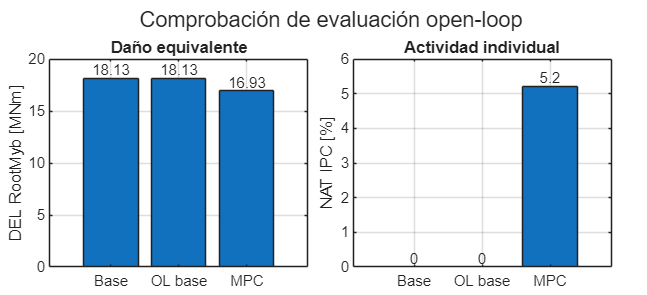


%% ============================================================
% FIGURA 8: validación open-loop, si existe OL base
% ============================================================

if any(tablaMPC_abs.Controlador == "OL base")

    controllersOL = ["Base", "OL base", "MPC"];
    controllersOL = controllersOL(ismember(controllersOL, tablaMPC_abs.Controlador));

    fig = figure('Color','w','Position',[100 100 1100 500]);
    tl = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

    nexttile;
    Y = getMetricByController(tablaMPC_abs, controllersOL, "DEL_RootMyb_mean_MNm");
    catsOL = categorical(controllersOL);
    catsOL = reordercats(catsOL, controllersOL);
    b = bar(catsOL, Y);
    grid on; box on;
    ylabel('DEL RootMyb [MNm]');
    title('Daño equivalente');
    addBarLabelsSingle(b, Y, 2);

    nexttile;
    Y = getMetricByController(tablaMPC_abs, controllersOL, "NAT_IPC_pitch_pct");
    b = bar(catsOL, Y);
    grid on; box on;
    ylabel('NAT IPC [%]');
    title('Actividad individual');
    addBarLabelsSingle(b, Y, 1);

    title(tl, 'Comprobación de evaluación open-loop');

    guardarFigura(fig, outFigDir, 'mpc_validacion_openloop');
end


fprintf('\nFiguras y tablas guardadas en:\n%s\n', outFigDir);


Figuras y tablas guardadas en:
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Figuras_Memoria\MPC


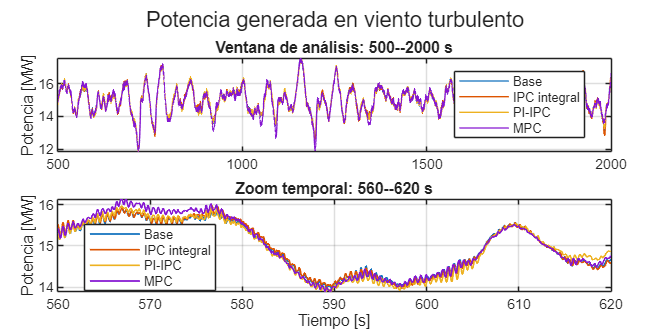


%% ============================================================
% FIGURA NUEVA: potencia temporal en viento turbulento
% Base vs IPC integral vs PI-IPC vs MPC
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

% Ventana completa de análisis
nexttile;
hold on;

for c = 1:numel(controllersMain)

    Sc = getStructCase(S, controllersMain(c));

    plot(Sc.t, Sc.GenPwr_MW, 'LineWidth', 0.8);
end

grid on; box on;
ylabel('Potencia [MW]');
title('Ventana de análisis: 500--2000 s');
legend(controllersMain, 'Location','best');
xlim([tTrans max(getStructCase(S,"Base").t)]);

% Zoom temporal
nexttile;
hold on;

for c = 1:numel(controllersMain)

    Sc = getStructCase(S, controllersMain(c));
    idx = Sc.t >= tZoom(1) & Sc.t <= tZoom(2);

    plot(Sc.t(idx), Sc.GenPwr_MW(idx), 'LineWidth', 1.0);
end

grid on; box on;
xlabel('Tiempo [s]');
ylabel('Potencia [MW]');
title(sprintf('Zoom temporal: %.0f--%.0f s', tZoom(1), tZoom(2)));
legend(controllersMain, 'Location','best');
xlim(tZoom);

title(tl, 'Potencia generada en viento turbulento');

guardarFigura(fig, outFigDir, 'mpc_potencia_turbulento_temporal');

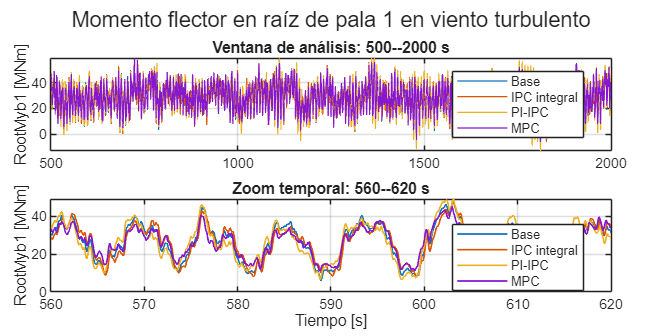


%% ============================================================
% FIGURA NUEVA: RootMyb1 temporal en viento turbulento
% Base vs IPC integral vs PI-IPC vs MPC
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

% Ventana completa de análisis
nexttile;
hold on;

for c = 1:numel(controllersMain)

    Sc = getStructCase(S, controllersMain(c));

    plot(Sc.t, Sc.RootMyb1_MNm, 'LineWidth', 0.75);
end

grid on; box on;
ylabel('RootMyb1 [MNm]');
title('Ventana de análisis: 500--2000 s');
legend(controllersMain, 'Location','best');
xlim([tTrans max(getStructCase(S,"Base").t)]);

% Zoom temporal
nexttile;
hold on;

for c = 1:numel(controllersMain)

    Sc = getStructCase(S, controllersMain(c));
    idx = Sc.t >= tZoom(1) & Sc.t <= tZoom(2);

    plot(Sc.t(idx), Sc.RootMyb1_MNm(idx), 'LineWidth', 1.0);
end

grid on; box on;
xlabel('Tiempo [s]');
ylabel('RootMyb1 [MNm]');
title(sprintf('Zoom temporal: %.0f--%.0f s', tZoom(1), tZoom(2)));
legend(controllersMain, 'Location','best');
xlim(tZoom);

title(tl, 'Momento flector en raíz de pala 1 en viento turbulento');

guardarFigura(fig, outFigDir, 'mpc_rootmyb1_turbulento_temporal');


%% ============================================================
% FUNCIONES AUXILIARES
% ============================================================

function [fileOutb, found] = localizarOutb(rootDir, priorityDirs, searchTerms, label)

    found = false;
    fileOutb = "";

    % 1) Probar carpetas prioritarias
    for i = 1:numel(priorityDirs)

        p = char(priorityDirs(i));

        if exist(p, 'dir')
            d = dir(fullfile(p, '**', '*.outb'));

            if ~isempty(d)
                fileOutb = fullfile(d(1).folder, d(1).name);
                found = true;
                return;
            end
        end
    end

    % 2) Búsqueda recursiva por términos en Resultados
    dAll = dir(fullfile(rootDir, 'Resultados', '**', '*.outb'));

    if isempty(dAll)
        return;
    end

    keep = true(numel(dAll),1);

    for k = 1:numel(searchTerms)

        term = lower(char(searchTerms(k)));

        hit = contains(lower({dAll.folder}), term) | contains(lower({dAll.name}), term);

        keep = keep(:) & hit(:);
    end

    d = dAll(keep);

    if isempty(d)
        return;
    end

    fprintf('\nCandidatos encontrados para %s:\n', label);

    for i = 1:numel(d)
        fprintf('%d) %s\n', i, fullfile(d(i).folder, d(i).name));
    end

    fprintf('Se usa el primero. Si no es correcto, cambia manualmente la carpeta .dir del caso.\n');

    fileOutb = fullfile(d(1).folder, d(1).name);
    found = true;
end

function S = leerCasoOpenFAST(fileOutb, controlador, tTrans)

    [data, chanNames, ~] = ReadFASTbinary(fileOutb);

    if ischar(chanNames)
        chanNames = string(cellstr(chanNames));
    else
        chanNames = string(chanNames);
    end

    chanNames = strtrim(chanNames);
    cleanNames = matlab.lang.makeValidName(chanNames);

    get = @(name) getChannel(data, cleanNames, name);

    S.controlador = char(controlador);

    t = get('Time');
    idx = t >= tTrans;

    S.t = t(idx);

    S.GenPwr_MW = get('GenPwr');
    S.GenPwr_MW = S.GenPwr_MW(idx);

    if mean(abs(S.GenPwr_MW), 'omitnan') > 1000
        S.GenPwr_MW = S.GenPwr_MW / 1000;
    end

    S.RotSpeed_rpm = get('RotSpeed');
    S.RotSpeed_rpm = S.RotSpeed_rpm(idx);

    b1 = get('BldPitch1');
    b2 = get('BldPitch2');
    b3 = get('BldPitch3');

    S.BldPitch_deg = [b1(idx), b2(idx), b3(idx)];
    S.BldPitchMean_deg = mean(S.BldPitch_deg, 2, 'omitnan');

    S.PtfmPitch_deg = get('PtfmPitch');
    S.PtfmSurge_m   = get('PtfmSurge');

    S.PtfmPitch_deg = S.PtfmPitch_deg(idx);
    S.PtfmSurge_m   = S.PtfmSurge_m(idx);

    S.Azimuth_deg = get('Azimuth');
    S.Azimuth_deg = S.Azimuth_deg(idx);

    r1 = get('RootMyb1');
    r2 = get('RootMyb2');
    r3 = get('RootMyb3');

    S.RootMyb1_MNm = r1(idx);
    S.RootMyb2_MNm = r2(idx);
    S.RootMyb3_MNm = r3(idx);

    if mean(abs(S.RootMyb1_MNm), 'omitnan') > 1000
        S.RootMyb1_MNm = S.RootMyb1_MNm / 1000;
        S.RootMyb2_MNm = S.RootMyb2_MNm / 1000;
        S.RootMyb3_MNm = S.RootMyb3_MNm / 1000;
    end

    psi = deg2rad(S.Azimuth_deg);

    S.Mtilt_MNm = (2/3) .* ( ...
        S.RootMyb1_MNm .* cos(psi) + ...
        S.RootMyb2_MNm .* cos(psi + 2*pi/3) + ...
        S.RootMyb3_MNm .* cos(psi + 4*pi/3));

    S.Myaw_MNm = (2/3) .* ( ...
        S.RootMyb1_MNm .* sin(psi) + ...
        S.RootMyb2_MNm .* sin(psi + 2*pi/3) + ...
        S.RootMyb3_MNm .* sin(psi + 4*pi/3));
end

function y = getChannel(data, cleanNames, name)

    nameClean = matlab.lang.makeValidName(name);

    idx = find(strcmpi(cleanNames, nameClean), 1);

    if isempty(idx)
        error('No se encuentra el canal: %s', name);
    end

    y = data(:, idx);
end

function y = demeanSignal(x)

    y = x - mean(x, 'omitnan');
end

function y = rmsDemean(x)

    x = x - mean(x, 'omitnan');
    y = sqrt(mean(x.^2, 'omitnan'));
end

function DEL = calcDEL(x, m, Neq)

    x = x(:);
    x = x - mean(x, 'omitnan');

    rf = rainflow(x);

    if istable(rf)
        ranges = rf.Range;
        counts = rf.Count;
    else
        counts = rf(:,1);
        ranges = rf(:,2);
    end

    DEL = (sum(counts .* ranges.^m, 'omitnan') / Neq)^(1/m);
end

function betaIPC = calcPitchIPC(beta)

    betaCol = mean(beta, 2, 'omitnan');
    betaIPC = beta - betaCol;
end

function rmsIPC = calcRMS_IPC(beta)

    betaIPC = calcPitchIPC(beta);
    rmsBlade = sqrt(mean(betaIPC.^2, 1, 'omitnan'));
    rmsIPC = mean(rmsBlade, 'omitnan');
end

function maxIPC = calcMax_IPC(beta)

    betaIPC = calcPitchIPC(beta);
    maxIPC = max(abs(betaIPC), [], 'all', 'omitnan');
end

function NAT = calcNAT(beta, t, pitchRateMax_deg_s)

    dt = diff(t(:));

    if any(dt <= 0)
        error('El vector de tiempo no es estrictamente creciente.');
    end

    rate = abs(diff(beta) ./ dt);

    meanAbsRate = mean(rate, 1, 'omitnan');

    NAT = 100 * mean(meanAbsRate, 'omitnan') / pitchRateMax_deg_s;
end

function y = getMetricByController(T, controllers, metric)

    y = nan(numel(controllers),1);

    for i = 1:numel(controllers)

        idx = T.Controlador == string(controllers(i));

        if ~any(idx)
            error('No encuentro controlador: %s', controllers(i));
        end

        y(i) = T.(metric)(idx);
    end
end

function Ssel = getStructCase(S, controlador)

    idx = find(strcmp(string({S.controlador}), string(controlador)), 1);

    if isempty(idx)
        error('No encuentro estructura para %s', controlador);
    end

    Ssel = S(idx);
end

function addBarLabelsSingle(b, Y, ndigits)

    xtips = b.XEndPoints;
    ytips = b.YEndPoints;
    labels = string(round(Y, ndigits));

    text(xtips, ytips, labels, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','bottom', ...
        'FontSize',9);
end

function addBarLabelsGrouped(b, Y, ndigits)

    for k = 1:numel(b)

        xtips = b(k).XEndPoints;
        ytips = b(k).YEndPoints;

        labels = string(round(Y(:,k), ndigits));

        text(xtips, ytips, labels, ...
            'HorizontalAlignment','center', ...
            'VerticalAlignment','bottom', ...
            'FontSize',8);
    end
end

function guardarFigura(fig, outDir, name)

    exportgraphics(fig, fullfile(outDir, [name '.png']), 'Resolution', 300);
    savefig(fig, fullfile(outDir, [name '.fig']));
end